# Profiling simulation with Reducer Basic model

Run simulation using the Solver Profiler's `solverprofiler.profileModel` function. See the documentation about the function for details.

- [https://www.mathworks.com/help/simulink/slref/solverprofiler.profilemodel.html](https://www.mathworks.com/help/simulink/slref/solverprofiler.profilemodel.html)

## Set up

model_name = "HarnessModel_Reducer";
target_folder = fullfile(currentProject().RootFolder, "Components", "Reducer", "Model-Basic", "SimulationCases");
data_fullpath = fullfile(target_folder, "profiling_data.mat");

## Run simulation normally

assert(isfolder(target_folder))
load_system(model_name);

% Close the Scope window to avoid getting the screenshot.
close_system(model_name + "/Measurement/Scope")
close_system(model_name + "/Measurement/Scope input torques")

Reducer_Basic_params

sim_in = Simulink.SimulationInput(model_name);

sim_in = setBlockParameter(sim_in, model_name + "/Axle inputs", ReferencedSubsystem = "Inputs_Reducer_AxleSide_Flip_refsub");
sim_in = setBlockParameter(sim_in, model_name + "/Motor inputs", ReferencedSubsystem = "Inputs_Reducer_MotorSide_Flip_refsub");

sim_in = setModelParameter(sim_in, StopTime = "150");

Run simulation normally and plot results.

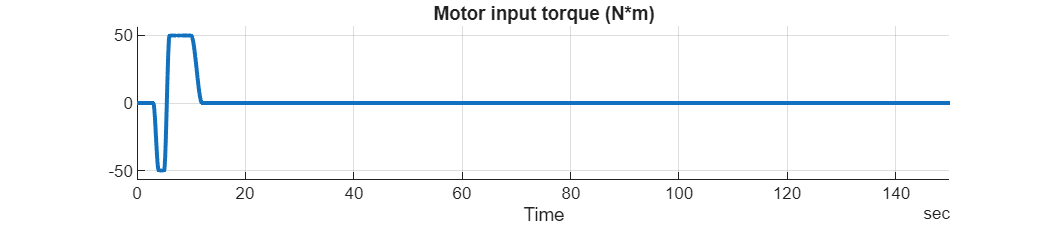

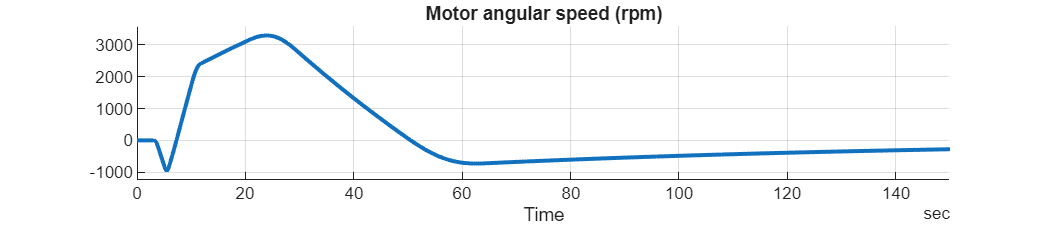

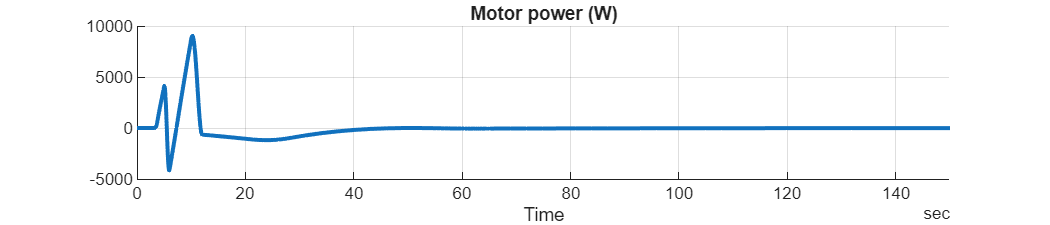

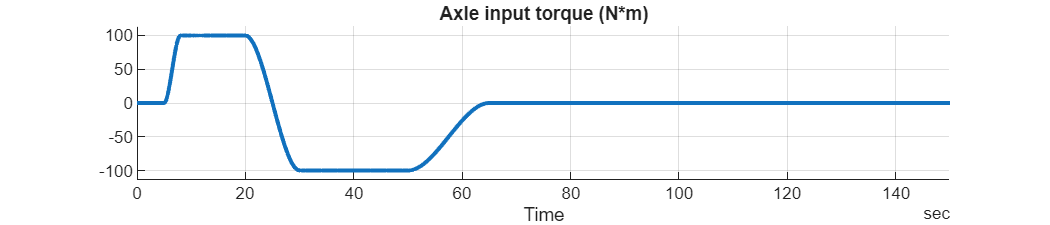

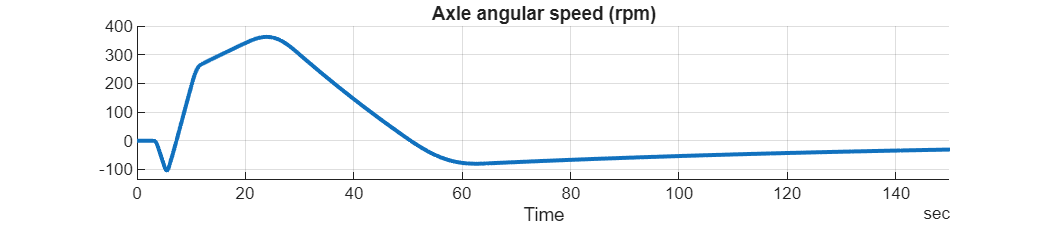

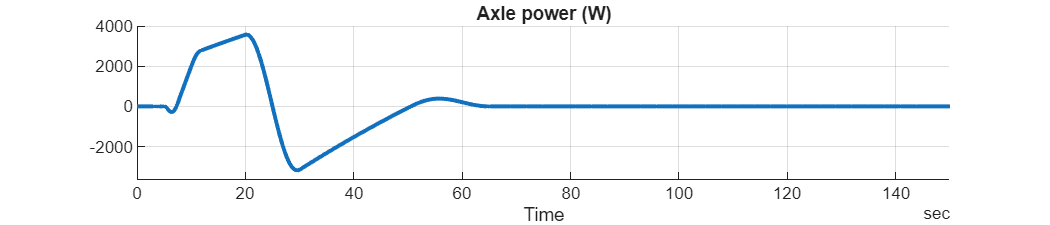

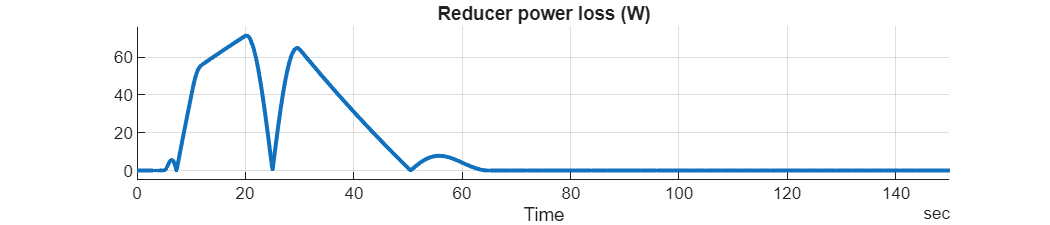

sim_out = sim(sim_in);
tt = SignalTool3.getTimetableFromLoggedSignal(sim_out.logsout);
varnames = string(tt.Properties.VariableNames);
for idx = 1 : numel(varnames)
  SignalTool3.plotTimedData(TimedData=tt, SignalName=varnames(idx), FigureHeight=150);
end  % for

## Step size

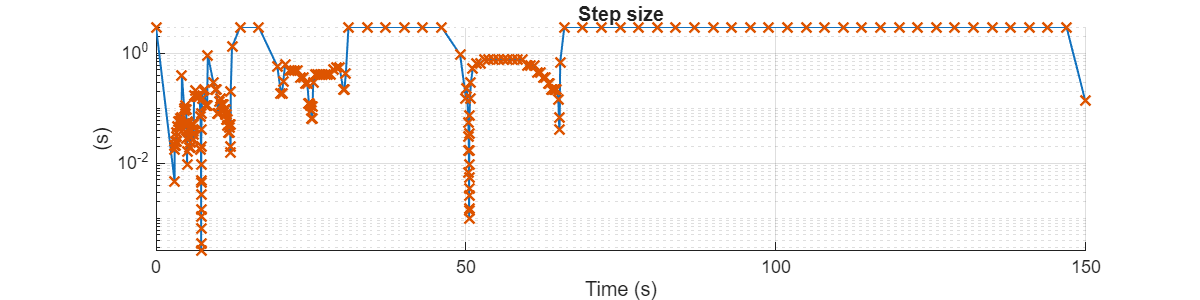

fig = figure;
fig.Position(3:4) = [800, 200];  % width, height
SignalTool3.plotDifference(sim_out.tout, NewFigure=false, ParentAxes=axes(fig), ...
  YScale = "Log", Title="Step size", YUnitText="s", ...
  XLabel="Time", XUnitText="s" )

step_size_data = diff(sim_out.tout);
disp("Maximum step size: " + max(step_size_data))

Maximum step size: 3


fprintf("Minimum step size: %e", min(step_size_data))

Minimum step size: 2.552514e-04

## Profiling simulation

Run profiling simulation using the Solver Profiler.

load_system(model_name)
result = solverprofiler.profileModel( ...
  model_name, ...
  DataFullFile = data_fullpath, ...
  OpenSP = "off", ... Set "on" to open the Solver Profiler after completing profiling.
  TimeOut = 10, ... in seconds. Stop the profiling simulation if the simulation does not make progress.
  StartTime = 0, ... Start time in seconds for profiling. Simulation starts from the model's StartTime which is usually 0.
  StopTime = 100, ... Stop time in seconds for simulation and profiling. The model's StopTime is not affected by this option.
  BufferSize = 50000, ... Maximum number of events to log.
  SaveStates = "on", ...
  SaveSimscapeStates = "on", ...
  SaveJacobian = "on", ...
  SaveZCSignals = "on" );

View the high-level summary of profiling result. See the documentation for details.

- `tStart` - Start time in seconds for profiling. Can be different from simulation start time.

- `tStop` - Stop time in seconds for profiling. Can be different from simulation stop time.

- `absTol` - Absolute tolerance for the solver.

- `relTol` - Relative tolerance for the solver.

- `hMax` - Maximum step size.

- `hAverage` - Average size of steps taken by the solver.

- `steps` - Total number of time steps.

- `profileTime` - Elapsed time in seconds.

- `zcNumber` - Number of zero crossings detected.

- `resetNumber` - Number of solver resets that occurred.

- `jacobianNumber` - Number of times the solver updated the Jacobian matrix.

- `exceptionNumber` - Total number of solver exceptions that occurred.

disp(result.summary)

             solver: 'auto(daessc)'
             tStart: 0
              tStop: 100
             absTol: 1.0000e-06
             relTol: 1.0000e-03
               hMax: 2
           hAverage: 0.6173
              steps: 162
        profileTime: 0.0306
           zcNumber: 0
        resetNumber: 1
     jacobianNumber: 26
    exceptionNumber: 62



Open the Solver Profiler with the saved session data.

%solverprofiler.exploreResult(char(data_fullpath))

*Copyright 2025-2026 The MathWorks, Inc.*